# DSB AM

%%symbolic
    syms t
    
    %signal frequency
    F1=1;
    m=1; %modulation factor
    PI=sym(pi)

$$PI = \pi$$

    
    %signal being sampled
        %sawtooth amplitude 1 Fequencey f -->abs(2*t*(F1)-2*floor(t*F1+1))-1
        %square--> sign(sin(ws*t))
        %triangle wave amp 1 centred about 0 make t t-1/2 for -1 at 0-->x=abs(4*(t*F1)-4*floor((t*F1)+1/2))-1
        x=abs(4*(t*F1)+2-4*floor((t*F1)+1))-1

$$x = \left|4\,t-4\,\left\lfloor t+1\right\rfloor +2\right|-1$$

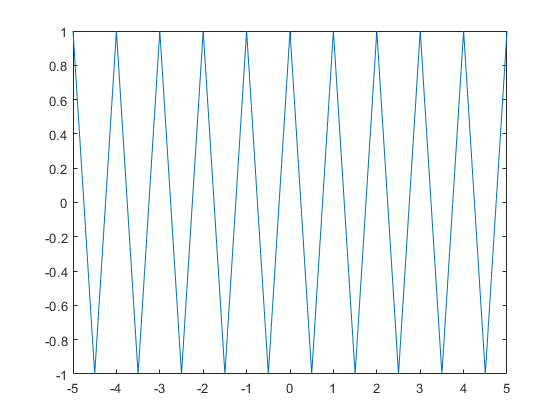

        fplot(x)    

        
    %%cariier freq
        Fc=20
    %%after modulation
        v=(x*m+1)*cos(2*pi*t*Fc)
    fplot(v,[0,2/F1])
        
    max_w=6*pi*max(F1,Fc);
    W_range=linspace(0,25*pi,1000)
    ffv=fourier(v)
    fplot(ffv,[-max_w,max_w]);
       xlabel('Frequency (in rad/s)');
       title('Magnitude Response');
%     F_resp=abs(subs(ffv,W_range));
%     plot(W_range,F_resp)
%%numeric

% %%initialisation
    f=2; %frequency of the impulse in Hz
    fs=max_w*10/pi; % sample frequency is 10 times higher
    time=-12:1/fs:12; % time vector
    num_V=double(subs(v,t,time))
    plot(time,num_V);
        
    N=size(time,2)
    Y = fftshift(fft(num_V));
   %%Frequency specifications:
   dF = fs/N;                      % hertz
   f = -fs/2:dF:fs/2-dF;           % hertz
   %%Plot the spectrum:
   figure;

   plot(f,abs(Y)/N,'DisplayName','absolute part')
   legend
   
   xlabel('Frequency (in hertz)');
   title('Magnitude Response');
    xlim([-fs/20 fs/20])
   hold off